Let's extend our example to the tracking problem.  Assuming a sampling time of 1 second, the system dynamics are given by 


$$x(k+1) = \pmatrix{1 & 1 \cr 0 & 1}x(k)+\pmatrix{0 \cr 1} u(k)$$



$$y(k) = \pmatrix{1 & 0}x(k)$$


 Let's use the objective function


$$J = \sum_{k=0}^{N-1}\left((y(k+1)-r(k+1))^2+\frac{1}{10}u(k)^2+\Delta u(k)^2\right)$$


and constrain the control inputs such that 


$$-1\leq u(k) \leq 1$$


For the tracking problem lets consider a square wave input.

Build the basic matrices for the problem. 

clear
A = [1 1;0 1];
B = [0;1];
C = [1 0];
R = 1/10;
RD = 1;  %Weight the slew rate - respect actuation bandwidths
Q = 1;  %Single output

I'm going to slightly more trouble here to make the horizon variable.

N = 100;  %This is the horizon for MPC
Qbar = [];
Rbar = [];
RbarD = [];
Sx = [];
Su = [];
CAB = [];
for ii = 1:N
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
    RbarD = blkdiag(RbarD,RD);
    Sx = [Sx;C*A^ii];
    CAB = [CAB;C*A^(ii-1)*B];
end
for ii = 1:N
    for jj = 1:ii
        Su(ii,jj) = sum(CAB(1:ii-jj+1));
    end
end
Su1=  Su(:,1);

Now convert into the form used by QP.  Precompute the components of F.

LL = tril(ones(N));
H = 2*(LL'*Rbar*LL+RbarD+Su'*Qbar*Su);
Fu = 2*(diag(LL'*Rbar')'+Su1'*Qbar*Su)';  %Note the trick on Rbar - u(-1) is really a scalar
Fr = -2*(Qbar*Su)';
Fx = 2*(Sx'*Qbar*Su)';

Now I have to think a bit more about these constraints for the tracking case.  I'm not constraining the slew rate, so my constraint really comes down to $|u(0)+\Delta u(k)|<1$.  The $W$ matrix will be updated at each step.

G = [tril(ones(N));-tril(ones(N))];
W0 = ones(2*N,1);
S = zeros(2*N,2);

The pre-computation is done.  Now let's look at an online solution using Matlab's **quadprog** command to solve the optimization problem.

Setup the initial condition and run the approach for T steps (in this case, T seconds).  For sanity's sake, I'll also turn off the reporting that quadprog typically does.

X = [0 ;0];
T = 40;
r = square([1:T+N+1]/6);
Z = zeros(2,1);
U = 0;
options = optimoptions('quadprog');
options.Display = 'none';
for ii = 1:T-1
    Xact(ii,:) = X; %For graphing
    f = Fx*X+Fu*U+Fr*r(ii:ii+N-1)';  %Sometimes people hold r(ii) here
    W = W0+[ones(N,1)*-U;ones(N,1)*U];

Solve the QP.

    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
    Uopt(ii) = U + Z(1);  %Just use the first item   
    U = Uopt(ii);

Now I'll apply the optimal control to the system.

    X = A*X+B*U;
end
Xact(ii+1,:) = X;

Now let's see how well that worked.

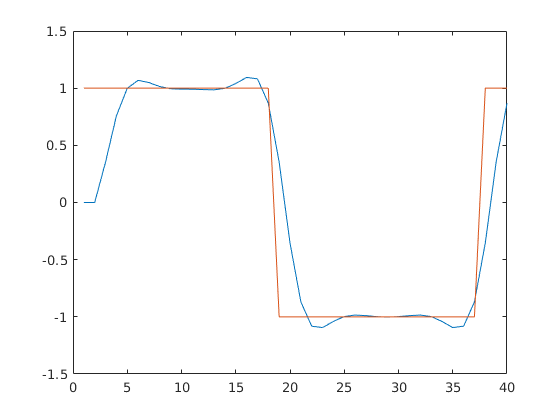

plot([1:T],Xact(:,1),[1:T],r(1:T))

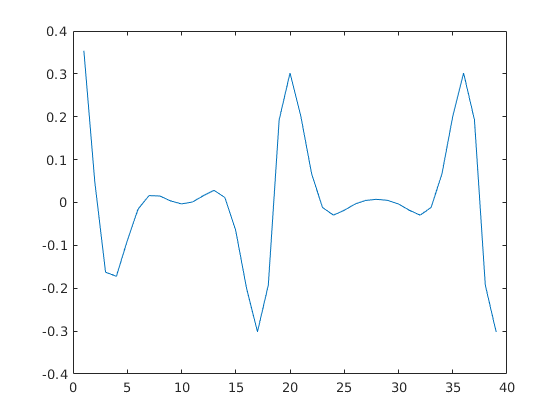

plot(Uopt)